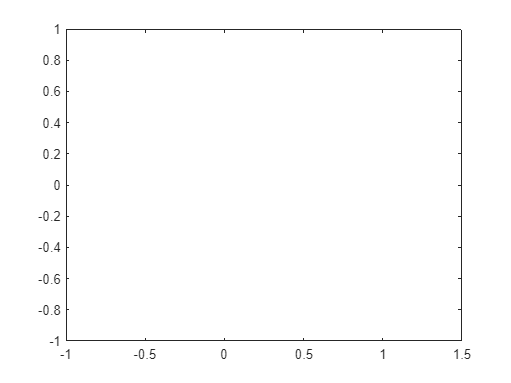

a=9*10^-9;
Eg_GaAs=1.424;
Eg_InAs=0.354;
Ve=(Eg_GaAs-Eg_InAs)*0.6;
Vh=(Eg_GaAs-Eg_InAs)*0.4;
me_eff_gaas=0.067;
mh_eff_gaas=0.45;
me_eff_inas=0.041;
q=1.60217663*10^-19;

mh_eff_inas=0.417;
m_0=9.1093837*10^(-31);
hbar=1.0545718*10^(-34);
n_sq=3;
Ee=(pi^2)*(hbar^2)*n_sq/(2*(a^2)*m_0*me_eff_inas);
Eh=(pi^2)*(hbar^2)*n_sq/(2*(a^2)*m_0*mh_eff_inas);
P_en=(Ee+Eh)+Eg_InAs;
mu=1/(1/(m_0*me_eff_inas)+1/(m_0*mh_eff_inas));
x=Ee+Eh;
eta=sqrt((2*mu*a^2*x*q)/(pi^2*hbar^2));

    xeta=0.02;   
    A=3;
    n_1=sqrt(A);
    relative_absorption_0=(1/(xeta*n_1.^2)).*exp((-(n_1./eta-1).^2)./(2*xeta^2));
    plot(P_en,relative_absorption_0)

% if (Ve>Ee) && (Vh>Eh) 
%     eta=sqrt((2*mu*a^2*x*q)/(pi^2*hbar^2));
% 
%     xeta=0.2;   
%     A=3;
%     n_1=sqrt(A);
%     relative_absorption_0=(1/(xeta*n_1.^2)).*exp((-(n_1./eta-1).^2)./(2*xeta^2));
%     plot(P_en,relative_absorption_0)
% end


hello

m_0=9.1093837*10^(-31);
hbar=1.0545718*10^(-34);
mu=1/(1/(m_0*me_eff)+1/(m_0*mh_eff));

Unrecognized function or variable 'me_eff'.

q=1.60217663*10^-19;
photon_energy=linspace(1.45,10);
x=photon_energy-E_g;
eta=sqrt((2*mu*L_0^2*x*q)/(pi^2*hbar^2));
Reduced_energy=eta.^2;
xeta=0.2;
A=3;
n_1=sqrt(A);
relative_absorption_0=(1/(xeta*n_1.^2)).*exp((-(n_1./eta-1).^2)./(2*xeta^2));
A=6;
n_2=sqrt(A);
relative_absorption_1=(1/(xeta*n_2.^2)).*exp((-(n_2./eta-1).^2)./(2*xeta^2));
A=9;
n_3=sqrt(A);
relative_absorption_2=(1/(xeta*n_3.^2)).*exp((-(n_3./eta-1).^2)./(2*xeta^2));
A=11;
n_4=sqrt(A);
relative_absorption_3=(1/(xeta*n_4.^2)).*exp((-(n_4./eta-1).^2)./(2*xeta^2));
superposition = relative_absorption_3+relative_absorption_2+relative_absorption_1+relative_absorption_0;
plot(Reduced_energy,relative_absorption_0)
hold on
grid on
plot(Reduced_energy,relative_absorption_0)
plot(Reduced_energy,relative_absorption_1)
plot(Reduced_energy,relative_absorption_2)
plot(Reduced_energy,relative_absorption_3)
plot(Reduced_energy, superposition,"--", Color="k")
hold off
[maxValue,maxIndex]=max(relative_absorption_0);
maxValue=Reduced_energy(maxIndex);
disp(['maximum relative absorption_0 : ',num2str(maxValue)]);
disp(['corresponding Reduced_energy : ',num2str(maxValue)]);
